# Using a ResNet for Brain Tumor Classification

## 1. Overview of the Problem: Detecting Tumors Using Neural Networks

**This application of neural networks for tumor detection was adapted from** Ismael, S. A. A., Mohammed, A., & Hefny, H. (2020). An enhanced deep learning approach for brain cancer MRI images classification using residual networks. *Artificial intelligence in medicine*, *102*, 101779.

### Summary

**Computer-Assisted Diagnosis** is a deep learning technology aimed to help doctors and radiologists diagnose and classify tumors using imaging data. While humans are really good at doing this task manually, the process is labor intensive. Approaches to facilitate and automate diagnosis would be decrease healthcare costs and time consumed for manual diagnosis.

This paper used **transfer learning** to train a **Residual Network (ResNet)** to classify three kinds of cancers from MRI images. We will go over the essential parts of transfer learning and a high level overview of what a ResNet does. 

## 2. Preliminary theory

### A. Convolutional Neural Networks

### 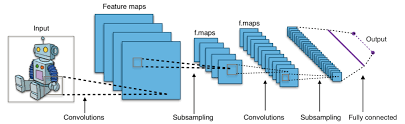

Image taken from [Wikimedia Commons](https://commons.wikimedia.org/wiki/File:Typical_cnn.png)

A **Convolutional Neural Network** consists of several additional layers that perform additional computations that are required to capture spatial information from an image. We'll briefy describe what these layers do.

#### Convolution Layer

An image can be represented as a **tensor**: a multi-dimensional matrix in terms of height, width, and the number of colors. For simplicity, we'll only consider gray-scale images, where there is only 1 color dimension. Thus, the image size is two-dimensional, with a height and width.

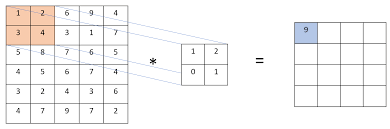

Image taken from [Wikimedia Commons](https://commons.wikimedia.org/wiki/File:Convolution.PNG)

In the convolution layer, we're scanning an image (left matrix) using a **filter** - a smaller matrix (middle) that can capture intrinsic features of the image (think edges, shades, etc). **The objective of the neural network is to learn the best set filters that can be generalized across different images to capture intrinsic data structures.** 

While the image is scanned, the area that is being scanned by the filter is beeing combined through **matrix multiplication**. The resulting matrix is called the** feature map** - a condensed representation of the image (right matrix). 

All together, this entire computational process is called a **convolution**.

#### Pooling Layer

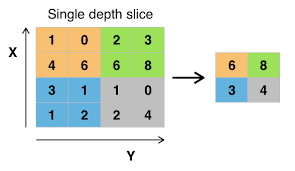

Image taken from [Wikimedia Commons](https://commons.wikimedia.org/wiki/File:Max_pooling.png).

Once we obtain a feature map, the data is condensed even further in the **pooling layer. **The purpose of the pooling layer is to **reduce the computational costs** downstream and **perform feature extraction** for the most important features in an image.   

#### Activation Layer: Rectified Linear Units (ReLUs)

We have seem what the sigmoid activation function does - it transforms data into the range of [0, 1], corresponding to probabilities. Now we will consider a new function: the **Rectified Linear Unit (ReLU)**.

The ReLU floors values to be 0 if the value is negative, or to be that value if positive. A plot of the ReLU distribution is shown below.

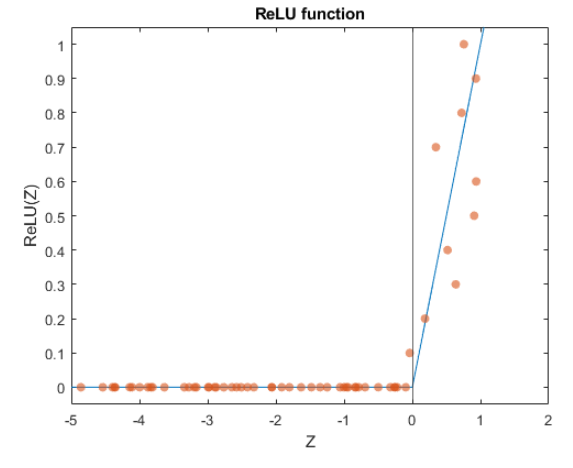

**There are several reasons why the ReLU performs well in neural networks**:

- The gradient during backpropagation is not saturated with a ReLU.

- The ReLU introduces sparsity and is a simple operation to perform, decreasing computational overhead.

#### Fully Connected Layer

From here, we perform a feedforward neural network computation. A schematic of the computation is shown below for review.

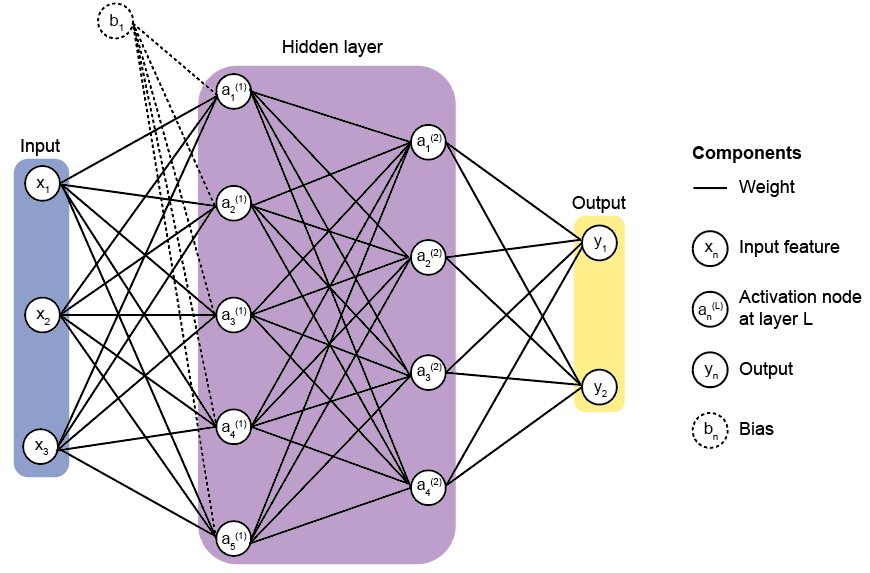

#### Loss Layer 

### B. Transfer learning

### C. Residual Networks

### D. Data Augmentation

## Load data

First, we'll load the MRI dataset from Swati et al (2019). Brain tumor classification for MR images using transfer learning and fine-tuning. *Computerized Medical Imaging and Graphics*, *75*, 34-46. 

### Description of the dataset

A full description of the dataset is in the README file. Important notes are bulleted below:

- Each `.mat` file is a structure labeled `.cjdata` and contains 5 fields

- The `label` field corresponds to diagnosis. 1 = meningioma, 2 = glioma, 3 = pituitary tumor.

- The `PID` field is the patient ID

- The `image` field is a 2D integer matrix of the image data, in grayscale

- The `tumorBorder` field is a vector storing coordinates of the tumor border. This was manually obtained.

- The `tumorMask` field is a binary image of the tumor region.

To download the dataset, go to this [link](https://figshare.com/articles/dataset/brain_tumor_dataset/1512427) and download the entire dataset (~1GB). They split the images into three folders. Put all the .mat files into a single folder called dataset. 

% Clear workspace
clear all
 
% Images Datapath – Please modify your path accordingly 
datapath='D:/Data/Brain_img/final_dataset';

Now we need to create a datastore object - a container MATLAB uses to read-in files.

% Image Datastore
imds = imageDatastore(fullfile(datapath), ...
                   'ReadFcn', @matRead, ...
                   'IncludeSubfolders', true, ...
                   'LabelSource', 'foldernames', ...
                   'FileExtensions','.mat');

## Visualize image

Let's read in a single file and visualize it.

img = readimage(imds, 1);

Note that if we visualize the image as is, the contrast is not that great. Our algorithm will also find it hard to distinguish edges as well.

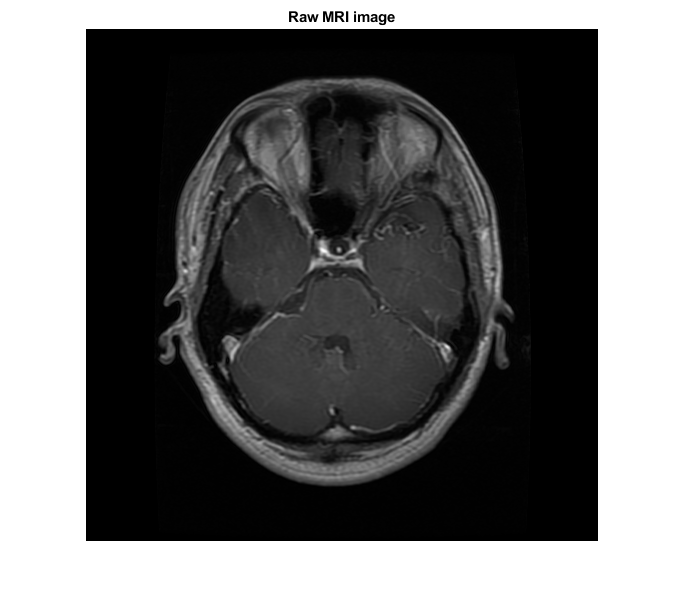

imshow(img);
title("Raw MRI image")

To fix this, we can perform a scaling method called min-max scaling. We make the smallest values 0 and the largest values 1. 

The formula and docstring for the MinMaxScale is show below.


$$X_{\mathrm{minmax}} =\frac{X_{\mathrm{ij}} -\mathrm{min}\left(X_j \right)}{\mathrm{max}\left(X_j \right)-\mathrm{min}\left(X_j \right)}$$


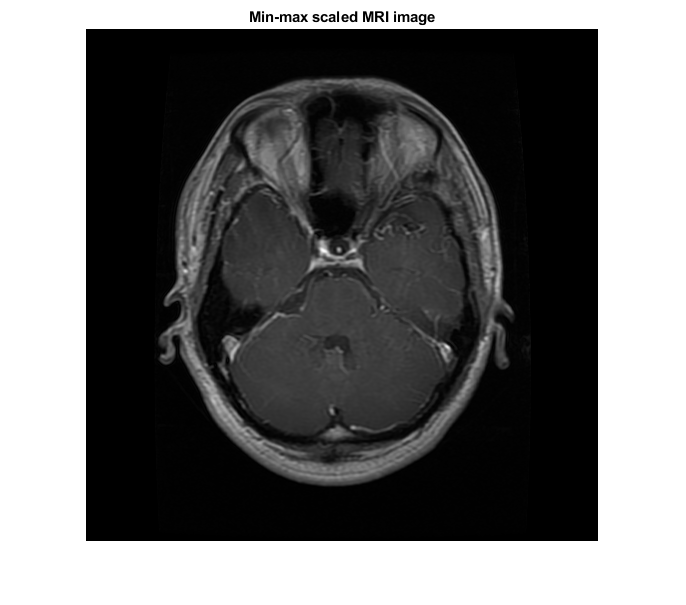

img = MinMaxScale(img);
imshow(img);
title("Min-max scaled MRI image");

## Training a ResNet using transfer learning

Now we'll implement transfer learning using the ResNet50 model for a simple classification task. 

### A. Balance dataset

First, let's count the number datapoints corresponding to each cateogory in the dataset.

tbl = countEachLabel(imds)

tbl = 3×2 table
      Label       Count
    __________    _____

    glioma        1426 
    meningioma     708 
    pituitary      930 


Note that we have an unequal number of images per catgory. Let's create a balanced dataset. Note that in practice, you would want to do the full 708 images. For our sake, we'll run this code on 100 images.

% Determine the smallest amount of images in a category
%minSetCount = min(tbl{:,2}); % FOR ALL 708 IMAGES
minSetCount = 100; 

% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');

% Notice that each set now has exactly the same number of images.
countEachLabel(imds)

ans = 3×2 table
      Label       Count
    __________    _____

    glioma         100 
    meningioma     100 
    pituitary      100 


### B. Loading the ResNet50 model

Now let's load the model. Note, you do have to download and install an additional MATLAB tooblox called **Deep Learning Toolbox Model for ResNet-50 Network.**

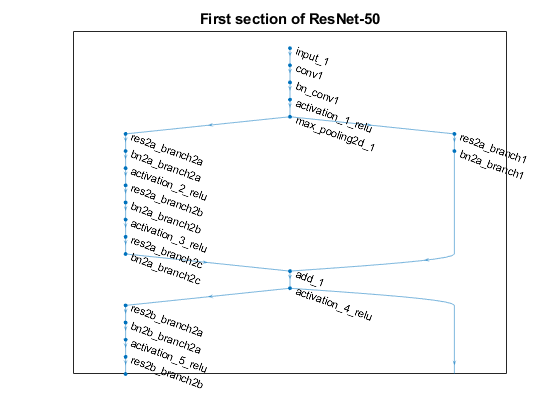

% ResNet Architecture  
net = resnet50();
figure;
plot(net)
title("First section of ResNet-50");
set(gca,'YLim',[150 170]);

Now let's create a copy of the network that we'll use for fine tuning.

CANCER_MDL = layerGraph(net);

### C. Create new layers for transfer learning.

We'll replace the fully connected layer at the head of the model - this contains all the fine-tuning weights that are specific for a given task. The layers we have to replace include:

- The fully connected layer

- The softmax layer

- The classification layer

% Fully connected layer
NUM_CLASSES = 3;
MRI_FC_LAYER    = fullyConnectedLayer(NUM_CLASSES, ...
                                      'Name', 'MRI_FC', ...
                                      'WeightLearnRateFactor', 10, ...
                                      'BiasLearnRateFactor',10);
CANCER_MDL      = replaceLayer(CANCER_MDL, 'fc1000', MRI_FC_LAYER);

% Softmax layer
MRI_SOFTMAX     = softmaxLayer('Name','MRI_Softmax');
CANCER_MDL      = replaceLayer(CANCER_MDL, 'fc1000_softmax', MRI_SOFTMAX);

% Classification layer
MRI_CLASSIFY   = classificationLayer('Name', 'CANCER_CLASSIFIER');
CANCER_MDL      = replaceLayer(CANCER_MDL, 'ClassificationLayer_fc1000', MRI_CLASSIFY);

### D. Create the training and test set

Now we can create a traning and test set. We'll do an 80/20 split.

[trainingSet, testSet] = splitEachLabel(imds, 0.2, 'randomize');

### E. Preprocess data images

To perform some data preprocessing, we'll perform the following steps:

- Resize the data to fit ResNet-50 specifications

- Add some augmentations to make the model more robust

- Apply to the dataset

% Data Augumentation
augmenter = imageDataAugmenter(...
                               'RandRotation', [-5 5], ...
                               'RandXReflection', 1, ...
                               'RandYReflection', 1, ...
                               'RandXShear', [-0.05 0.05], ...
                               'RandYShear', [-0.05 0.05]);

IMG_DIM = net.Layers(1).InputSize;
augTrainData  = augmentedImageDatastore(IMG_DIM, ...
                                        trainingSet, ...
                                        'DataAugmentation', augmenter, ...
                                        'ColorPreprocessing', 'gray2rgb');
augTestData   = augmentedImageDatastore(IMG_DIM, ...
                                        testSet, ... 
                                        'ColorPreprocessing', 'gray2rgb');

### F. Specify model hyperparameters

Now let's specify some model hyperparameters.

% Training Options, we choose a small mini-batch size due to limited images 
options = trainingOptions(...
                          'adam',...                     % ADAM Optimization
                          'MaxEpochs', 10, ...           % Number of epochs without early stopping
                          'MiniBatchSize', 8,...         % Mini-batches (don't worry about it)
                          'Shuffle','every-epoch', ...   % Shuffling data 
                          'InitialLearnRate', 1e-4, ...  % Initial learning rate - related to ADAM
                          'Verbose', true, ...           % Show warnings if any
                          'Plots','training-progress');  % Show model progress

### F. Model training

Now that we've set up the model and the data, let's train the new model.

% Training
[MRI_ResNet, trainingInfo] = trainNetwork(augTrainData, CANCER_MDL, options);

Training on single GPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:03 |       37.50% |       1.2190 |      1.0000e-04 |


|       8 |          50 |       00:00:48 |      100.00% |       0.0404 |      1.0000e-04 |


|      10 |          70 |       00:01:07 |       62.50% |       0.8148 |      1.0000e-04 |
|========================================================================================|


Once the model has been trained, we'll classify the labels.

[predicted_labels, posterior] = classify(MRI_ResNet, augTestData);

### G. Validation

Let's visualize the results using a confusion matrix.

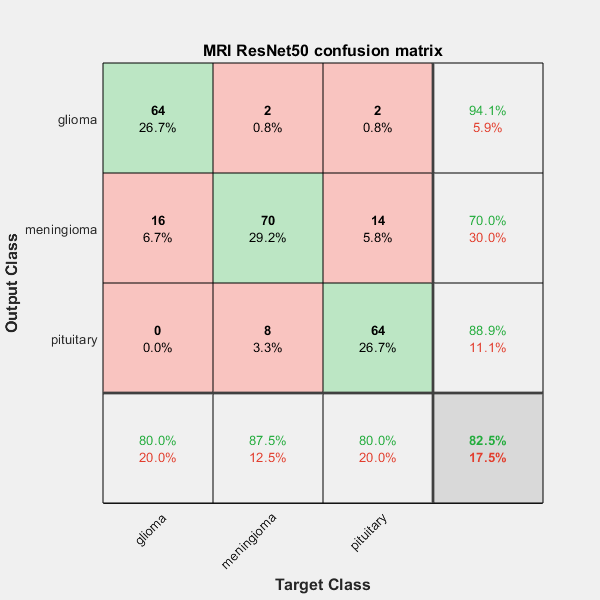

figure;
plotconfusion(testSet.Labels, predicted_labels)
title('MRI ResNet50 confusion matrix');

## Summary